# Plotting LIDAR data in Global Frame

Objective:  This script will show you how to use both the  the *range2xy * and *transform_points* functions to transform LIDAR data to plot it in the **global frame.** This script uses the the robot pose to transform the data from the sensor frame to the robot frame using transform_points and plot your results

Helper Functions used in this exercise:

- *plot_frames: *plots a data point both in the robot frame and the global frame.The robot is a black circle with a radius pointing in its positive x direction, and the data points are represented by red dots, which typically form a line. 

Exercise:

In the Simulator, press the Read Sensors button to get the CreateRobot object that represents the current state of the robot. You will use the object (named **robotObj**) in this script.

Initialize the robot constants. Define the robot's radius based on the CreateRobot class variable **robotObj **for the radius and assign this to the variable robotRadius*.*  Define the LIDAR pose based on the robot’s radius in the robot reference frame; asign this to the variable lidar_pose. Remember that the robot reference frame always defines the robot position at [0; 0; 0], therefore this definition of the LIDAR pose will be constant no matter where the robot is in the global frame. This LIDAR pose is needed to transform data from the sensor frame to the robot frame. 

**COMPLETE THE CODE BELOW **

%Initialize robot constants
robotRadius = robotObj.radius;%Insert your code here
lidar_pose = [robotRadius;  0;  0];%Insert your code here


Read the LIDAR data. 

% Initialize, get LIDAR Constants
angRangeLidar = robotObj.angRangeLidar;
rangeLidar = robotObj.rangeLidar;
numPtsLidar = robotObj.numPtsLidar;
angleData= robotObj.angleArray; 

% Get LIDAR data, this is a row vector with length = numPtsLid
distLidar= genLidar(robotObj);

Get the current pose of the robot using the robotObj, define the robot pose and assign to the variable robot_pose. Hint: you learned how to do this in the pre-req

**COMPLETE THE CODE BELOW **

%Read the current position of the robot from the overhead
%  x, y and th, not a vector containing those values
[x, y, th]= genOverhead(robotObj);%Insert your code here
robot_pose = [x; y; th];  %Insert your code here

Using *range2xy, * transform the lidar sensor output to x-y cooridnates (in the sensor frame). Then, using the *transform_points* function, transform the data from the Sensor Frame to the Robot Frame. 

As you did in the *plot_LIDAR_xy_sensor*, transform the LIDAR output to xy coordinates and assign to the variable dataxy_sensor. 

**COMPLETE THE CODE BELOW **

dataxy_sensor = range2xy(angleData',distLidar',rangeLidar); %Insert your code here

Transform the xy coordinates from sensor frame to robot frame using your *transform_points* function and assign to the variable dataxy_robot. How do the inputs of the *transform_points *function differ from when we used it to transform points from the robot to the global frame?

**COMPLETE THE CODE BELOW **

dataxy_robot = transform_points(lidar_pose,dataxy_sensor);%Insert your code here

There should not be much difference between the Sensor and Robot Frame since the sensor is along the x-axis and only robot radius is relatively small. Now transform the data from the robot frame to the global frame using *transform_points* and assign to the variable dataxy_global

**COMPLETE THE CODE BELOW **

dataxy_global = transform_points(robot_pose,dataxy_robot);%Insert your code here

Plot Results

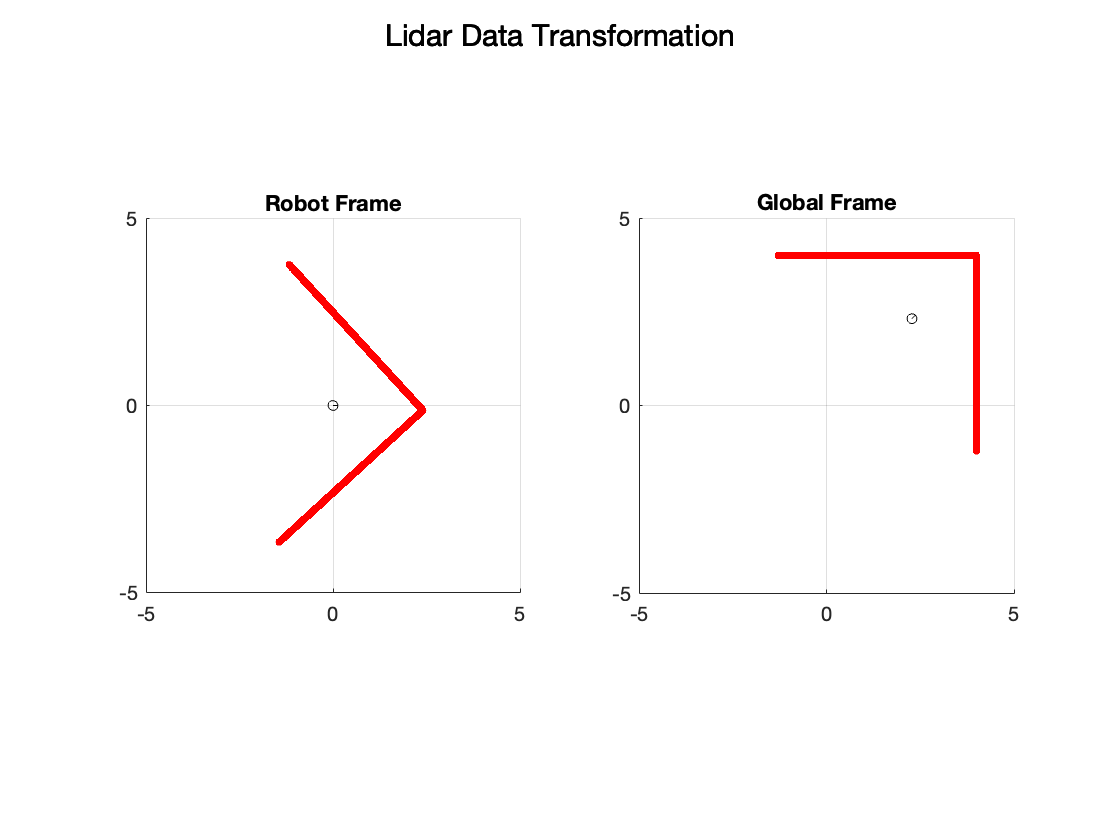

%Plot
figure; 
plot_title = "Lidar Data Transformation";
plot_frames(robot_pose, dataxy_robot, dataxy_global, plot_title);
set(gcf,'Visible','on'); 

Expected Results: Because you are plotting the LIDAR data in the **global frame**, you should see the sensor readings as you would see the map in the simulator. If the implemenation is correct, robot and global frame plots should look the same with respect to the robot heading. 

Check your Comprehension:

How do the two plots differ? Given the orientation of the robot, does the difference between the robot and global frame make sense? Move the robot around the map facing different obstacles and compare the plots. 